https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html#mw_70f735e2-7aa7-43a2-97e8-a1ef36640a04

Variables

75,1,1 -> sin wave //ocilates

75,-1,1 -> -ve exponential // toward equilibrium 

75,1,-1 -> +ve exponential 

75,-x,x -> as x increases, fplot(Sol) tends to straight line y = -x+3ish

75,x,-x -> as x increases, fplot(Sol) tends to straight line y = x+3ish

R = 75

R = 75

L = -7

L = -7

C = 7

C = 7

ZIR Equation

syms V0(t)
DV0 = diff(V0) 

$$DV0(t) = \frac{\partial }{\partial t}V_{0}\left(t\right)$$

odeZIR = diff(V0,t,2) + (1/(R*C))*diff(V0,t) + (1/(L*C))*V0 == 0

$$odeZIR(t) = \frac{\partial^{2}}{\partial t^{2}}V_{0}\left(t\right)+\frac{\frac{\partial }{\partial t}V_{0}\left(t\right)}{525}-\frac{V_{0}\left(t\right)}{49}=0$$

Initial conditions

condition1 = V0(0) == 3

$$condition1 = V_{0}\left(0\right)=3$$

condition2 = DV0(0) == -(77/(25*C))

$$condition2 = \left({\left(\frac{\partial }{\partial t}V_{0}\left(t\right)\right)|}_{t=0}\right)=-\frac{11}{25}$$


condsZIR = [condition1,condition2]

$$condsZIR = \left(\begin{array}{cc} V_{0}\left(0\right)=3 & \left({\left(\frac{\partial }{\partial t}V_{0}\left(t\right)\right)|}_{t=0}\right)=-\frac{11}{25} \end{array}\right)$$


SolZIR = dsolve(odeZIR)

$$SolZIR = C_{1}\,{\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}+C_{2}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}$$


FullSolZIR(t) = dsolve(odeZIR,condsZIR)

$$FullSolZIR(t) = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}\,\left(\frac{459\,\sqrt{22501}}{45002}+\frac{3}{2}\right)+\frac{3\,\sqrt{22501}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}\,\left(\sqrt{22501}-153\right)}{45002}$$

FullSolZIR = simplify(FullSolZIR(t))

$$FullSolZIR = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}\,\left(\frac{459\,\sqrt{22501}}{45002}+\frac{3}{2}\right)+\frac{3\,\sqrt{22501}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}\,\left(\sqrt{22501}-153\right)}{45002}$$

Plotting

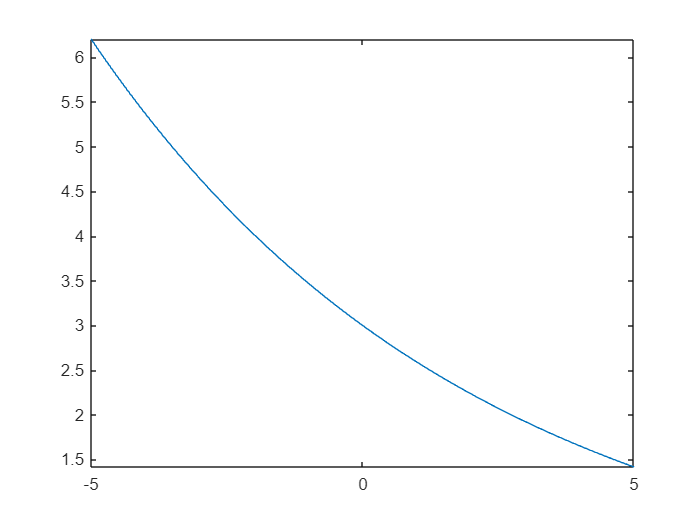

fplot(FullSolZIR)

UIR Equation

syms Vn(t)
DVn = diff(Vn)

$$DVn(t) = \frac{\partial }{\partial t}\mathrm{Vn}\left(t\right)$$

odeUIR = diff(Vn,t,2) + (1/(R*C))*diff(Vn,t) + (1/(L*C))*Vn == 0

$$odeUIR(t) = \frac{\partial^{2}}{\partial t^{2}}\mathrm{Vn}\left(t\right)+\frac{\frac{\partial }{\partial t}\mathrm{Vn}\left(t\right)}{525}-\frac{\mathrm{Vn}\left(t\right)}{49}=0$$

Initial cnditions

condition3 = Vn(0) == 0

$$condition3 = \mathrm{Vn}\left(0\right)=0$$

condition4 = DVn(0) == 1

$$condition4 = \left({\left(\frac{\partial }{\partial t}\mathrm{Vn}\left(t\right)\right)|}_{t=0}\right)=1$$


condsUIR = [condition3,condition4]

$$condsUIR = \left(\begin{array}{cc} \mathrm{Vn}\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}\mathrm{Vn}\left(t\right)\right)|}_{t=0}\right)=1 \end{array}\right)$$


SolUIR = dsolve(odeUIR)

$$SolUIR = C_{1}\,{\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}+C_{2}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}$$


FullSolUIR(t) = dsolve(odeUIR,condsUIR)

$$FullSolUIR(t) = \frac{525\,\sqrt{22501}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}}{22501}-\frac{525\,\sqrt{22501}\,{\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}}{22501}$$

FullSolUIR = simplify(FullSolUIR(t))

$$FullSolUIR = \frac{525\,\sqrt{22501}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{22501}+1\right)}{1050}}\,\left({\mathrm{e}}^{\frac{\sqrt{22501}\,t}{525}}-1\right)}{22501}$$


syms h(t) u(t)

odeH = h(t) == (1/C)*diff(FullSolUIR,t)*u(t)

$$odeH = h\left(t\right)=u\left(t\right)\,\left(\frac{{\mathrm{e}}^{\frac{\sqrt{22501}\,t}{525}}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{22501}+1\right)}{1050}}}{7}-\frac{75\,\sqrt{22501}\,{\mathrm{e}}^{-\frac{t\,\left(\sqrt{22501}+1\right)}{1050}}\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)\,\left({\mathrm{e}}^{\frac{\sqrt{22501}\,t}{525}}-1\right)}{22501}\right)$$


condition5 = u(t<0) == 0

$$condition5 = u\left(t<0\right)=0$$

condition6 = u(t>=0) == 1

$$condition6 = u\left(0\leq t\right)=1$$


condsH = [condition5,condition6]

$$condsH = \left(\begin{array}{cc} u\left(t<0\right)=0 & u\left(0\leq t\right)=1 \end{array}\right)$$

Plotting

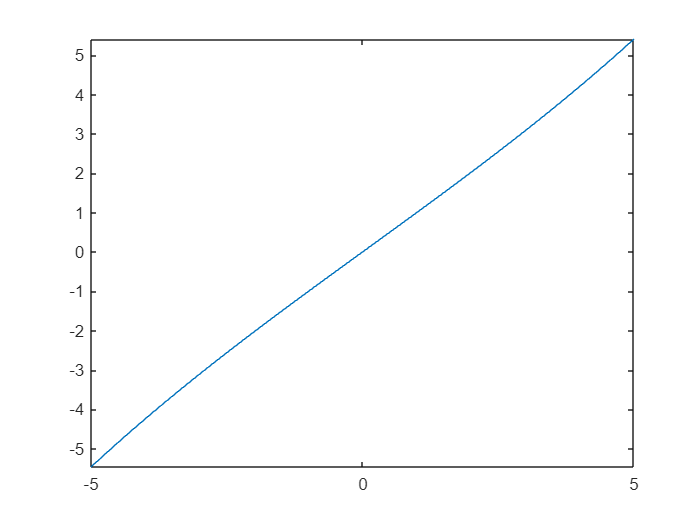

fplot(FullSolUIR)